Rovnice naší bázové funkce bude sinus s proměnou frekvencí:


$$y=\sin \left(x*q\right)$$


kde $q$ ovlivňuje frekvenci křivky. Naše křivka tedy vypadá následovně:


$$\textrm{výška}=\sin \left(\textrm{váha}*q\right)$$
  

Máme tedy úlohu pouze s jedním parametrem, který chceme nastavit tak, aby aproximace byla co možná nejlepší. Takže úloha je právě ono hledání vhodného parametru.

Naše naměřená data jsou:


$$\left\lbrack \begin{array}{cccc}
\textrm{výška} & 1,4 & 1,9 & 3,2\\
\textrm{váha} & 0,5 & 2,3 & 2,9
\end{array}\right\rbrack$$


Zkusme je aproximovat třeba sínusovkou.

vyska = [1.4 1.9 3.2];
vaha = [0.5 2.3 2.9];
plot(vaha,vyska,"ro");
hold on;

Nejprve si musíme vytvořit tzv. **ztrátovou funkci **$E$ (Loss function). V našem případě se bude jednat o vztah vyjadřující sumu všech kvadratických rozdílů naší aproximované křivky a naměřených dat. Tento vztah se nazývá metoda nejmenších čtverců a je velmi často používána pro hledání aproximace.

#### 
$$\begin{array}{l}
E=\sum_{n_0 }^N {\left(y_{\textrm{naměřené}} -y_{\textrm{aproximovaé}} \right)}^2 \\
E=\sum_{n_0 }^N {\left(y_{\textrm{naměřené}} -\left(\sin \left(x_{\textrm{naměřené}} *q\right)\right)\right)}^2 \\
E={\left(1,4-\left(\sin \left(0,5*q\right)\right)\right)}^2 +{\left(1,9-\left(\sin \left(2,3*q\right)\right)\right)}^2 {\;+\;\left(3,2-\left(\sin \left(2,9*q\right)\right)\right)}^2 
\end{array}$$


kde $N$je počet všech naměřených dat, a $q$ je parametr, který hledáme. Takže máme vyčíslenou ztrátovou funkci a mohu začít pátrat po optimálním řešení. Pozor! My neznáme jaká ta minimální hodnota $E$ bude, takže nelze za $E$dosadit prostě třeba hodnotu nula a analiticky dopočítat přesnou hodnotu parametru $q$.  Samozřejmě by nás také mohlo napadnout, za parametr $q$ prostě začít dosazovat náhodné čísla a s trochou štěstí bychom i nějaké jakési minimum této funkce dostali, ale my to uděláme trochu sofistikovaněji pomocí metody největšího spádu (Gradient Decent). 

Ta sofistikovanost bude následující. Využijeme totiž toho, že lokální extrémy funkce mají derivaci rovnou nule. Pokud jsme tedy v minimu naší ztrátové funkce, tak musí být její derivace rovna nule. Zde by mohl nastat problém, pokud by ztrátová funkce obsahovala více lokálních extrémů, ale jelikož je naše ztrátová funkce kvadrát odchylek, čili parabola, tak víme, že parabola obsahuje lokální extrém pouze jeden a to globální minimum, které se právě snažíme nalézt. 

Takže provedeme derivaci naší ztrátové funkce podle parametru $q$. Derivace ztrátové funkce je rovna derivaci všech jednotlivých členů sumy, tím pádem:

#### 
$$\frac{\partial E}{\partial q}=\sum_{n_0 }^N \frac{{\partial \left(y_{\textrm{naměřené}} -\left(\left.\sin \left(x_{\textrm{naměřené}} *q\right)\right)\right)\right)}^2 }{\partial q}=\sum_{n_0 }^N 2\left(y_{\textrm{naměřené}} -\left(\sin \left(x_{\textrm{naměřené}} *q\right)\right)\right)*-\cos \left(x_{\textrm{naměřené}} *q\right)=\sum_{n_0 }^N -2*\cos \left(x_{\textrm{naměřené}} *q\right)*\left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)$$


#### 
$$\frac{\partial E}{\partial q}=\frac{{\partial \left(1,4-\left(\sin \left(0,5*q\right)\right)\right)}^2 }{\partial q}+\frac{{\partial \left(1,9-\left(\sin \left(2,3*q\right)\right)\right)}^2 }{\partial q}+\;\frac{{\partial \left(3,2-\left(\sin \left(2,9*q\right)\right)\right)}^2 }{\partial q}$$


#### 
$$\frac{\partial E}{\partial q}=$$

$$\left(-2*\cos \left(0,5*q\right)*\left(1,4-\left(\sin \left(0,5*q\right)\right)\right)\right)+\left(-2*\cos \left(2,3*q\right)*\left(1,4-\left(\sin \left(2,3*q\right)\right)\right)\right)+\left(-2*\cos \left(2,9*q\right)*\left(1,4-\left(\sin \left(2,9*q\right)\right)\right)\right)$$


Derivace složené funkce je derivace vnitřní funkce krát derivace vnější funkce, takže výsledek je vidět výše. Takže nyní máme připravenou derivaci ztrátové funkci a můžeme začít hledat minimum. Nejdříve si zvolíme náhodnou hodnotu našeho parametru $q$. např. $q=0$ a následně zjistíme, jakou má ztrátová funkce v tomto bodě hodnotu derivace pouhým dosazením za parametr $q$. Pokud hodnota derivace v tomto bodě není nulová, tak bychom potřebovali změnit hodnotu $q$ tak, aby jsme se k minimu přiblížili. Otázka nyní zní, zda parametr zvyšovat či snižovat a o kolik. Odpoveď na tuto otázku nám dá výsledek, který jsme získali dosazením parametru $q$ do derivace ztrátové funkce. Hodnota derivace nám totiž říká, zda ztrátová funkce v tomto bodě roste (kladná hodnota derivace), nebo kelsá (záporná hodnota derivace) a velikost této hodnoty také odpovídá tomu jak rychle hodnota klesá, či roste. Takže nyní musíme ve směru (pokud ztrátová funkce v tomto bodě klesá, tak parametr zvyžuji a pokud naopak roste, tak parametr zvyšuji) upravit parametr. K jeho úpravě použijeme ještě přenásobení spočtené hodnoty derivace v daném bodě tzv. koeficientem učení $\alpha$. Koeficient učení $\alpha$ nám ovlivňuje "velikost kroku" z daného bodu do nového. Pokud volíme koeficient učení příliš malý, metodě bude déle trvat, než ke správné hodnotě dokonverguje. Pokud naopak volíme koeficient učení příliš velký, může se nám naopak stát, že metoda bude dokonce divergovat (krok se provede přes minimum do hodnoty ztrátové funcke ještě vyšší, než byla v bodě, ze kterého jsme výpočet prováděli). Koeficient učení lze zvolit tedy např. $\alpha \;=0,1$. 

Zkusme si tedy dosadit "náhodný" počáteční bod pro naše odvození derivace ztrátové funkce výše. 

####  
$$\frac{\partial E}{\partial q}=$$

$$\left(-2*\cos \left(0,5*0\right)*\left(1,4-\left(\sin \left(0,5*0\right)\right)\right)\right)+\left(-2*\cos \left(2,3*0\right)*\left(1,4-\left(\sin \left(2,3*0\right)\right)\right)\right)+\left(-2*\cos \left(2,9*0\right)*\left(1,4-\left(\sin \left(2,9*0\right)\right)\right)\right)=-8,4$$


Výsledkem je $-8,4$ , čili víme, že musíme hodnotu parametru snížit. Koeficient učení zvolíme oněch $0,01$, tím pádem parametr nakonec bude mít hodnotu:

#### 
$$q_{\textrm{nový}} =q_{\textrm{původní}} -\left(\frac{\partial E}{\partial q}*\alpha \right)$$


#### 
$$q_{\textrm{nový}} =0-\left(\left(-8,4\right)*0,01\right)$$


#### 
$$q_{\textrm{nový}} =0,84$$


Tímto výpočtem jsem tedy získal novou hodnotu parametru $q$. Novou hodnotu opět dosadíme do odvozené derivace ztrátové funkce a zjistíme, jestli se již rovná nule. Pokud ano, výpočet je u konce a my našli optimální hodnotu parametru $q$. Pokud ale gradient není nulový, tak stejným způsobek jako výše upravíme parametr $q$. Tento proces provádíme tak dlouho, dokud parametr $q$ nebude roven nule. Přesněji řečeno se málo kdy povede nalézt přesně nulovou derivaci ztátové funkce, proto typicky volíme určitou toleranci $\tau$, při které nám již přesnost aproximace stačí. Tato tolerance může být v našem příkaldu třeba $\tau \;=0,01$.

Teď to celé zkusíme naházet do kódu. Data z tabulky máme již připravené z kódu nahoře, takže zde připravím jen symbolickou proměnou parametru $q$, koeficient učení $\alpha$ a toleranci $\tau$ 

alpha = 0.01;   % míra učení
tau = 0.01;     % maximální možná chyba pro ukončení výpočtu
syms q_sym;

Nyní si vyjádříme ztrátovou funkcí ve tvatu metody nejmenších čtverců.

E_sym = sum((vyska - (sin(q_sym*vaha))).^2);

 A ztrátovou funkci derivujeme.

dE_sym = diff(E_sym,q_sym);

Nyní si ještě naplníme první parametr náhodnou hodnotou, v našem případě nulou. Pro jméno koeficientu zvolíme odlišné jméno, než pro jméno symbolické jméno koeficientu, aby nám program fungoval.

q = 0;

V tuhle chvíli mám vše co je potřeba, takže mohu iteračně provádět hledání nových a stále přesnějších parametrů $q$, dokud nebude dosažena požadovaná přesnost, nebo dokud nebude dosaženo maximálního počtu iterací. V našem případě jsme zvolili maximální počet iterací $\textrm{1000}$.

for i = 1:1000 
    dE = (double(subs(dE_sym,q_sym,q)));
    if abs(dE) < tau
        break;
    end
    q = q - dE*alpha
end

q = 2.0420

q = 2.0882

q = 2.1369

q = 2.1862

q = 2.2350

q = 2.2821

q = 2.3266

q = 2.3669

q = 2.4017

q = 2.4301

q = 2.4523

q = 2.4690

q = 2.4812

q = 2.4901

q = 2.4965

q = 2.5011

q = 2.5043

q = 2.5067

q = 2.5083

q = 2.5095

q = 2.5103

q = 2.5109

q = 2.5113

q = 2.5116

q = 2.5118

q = 2.5119

q = 2.5120

q = 2.5121

q = 2.5122

q = 2.5122

q = 2.5122

q = 2.5123

q = 2.5123

Zkusíme si aproximaci vykreslit do grafu.

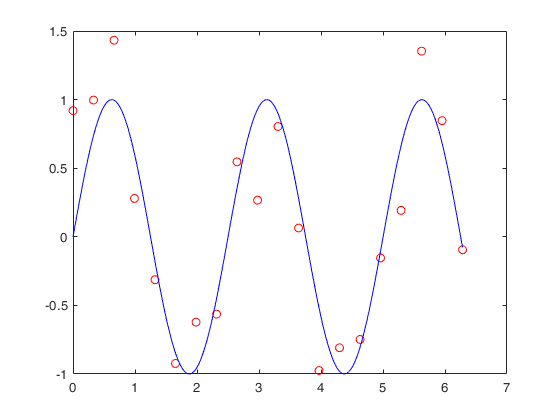

plot(0.5:0.1:3,sin((0.5:0.1:3).*q),"b-");
hold off;

To nevypadá jako ideální aproximace. Tak tedy co je špatě? No hned několik věcí. Za prvné parametr pouze mění frekvenci harmonické funkce sínus, ale nikoliv její amplitudu, čili funkční hodnota této křivky nikdy nepřesáhne hodnotu jedna. To je trochu nemilé, když všechny naše body mají funkční hodnotu vyšší než jedna$\left(1,4\;\;\;\;\;\;\;\;\;1,9\;\;\;\;\;\;\;\;3,2\right)$. Tudíž parametr nemá na aproximaci zas takový vliv. Ale je tu ještě jeden podstaný problém. Proto se pojďme podívat na ztrátovou funkci a na její derivaci.

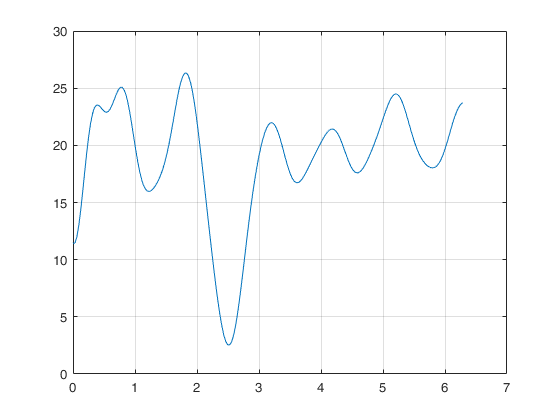

plot(0:0.1:3,double(subs(E_sym,q_sym,0:0.1:3)));
grid on;

Z grafu ztrátové funkce je patrné, že se již nejedná o jednoduchou parabolu. Jedná se o složitější funkcí s hned několika lokálními minimy. To znamená, výpočet gradientu nemusí směřovat do jednoho globálního minima, ale může klidně skončit v nějakém lokálním minimu. A to je velký problém.

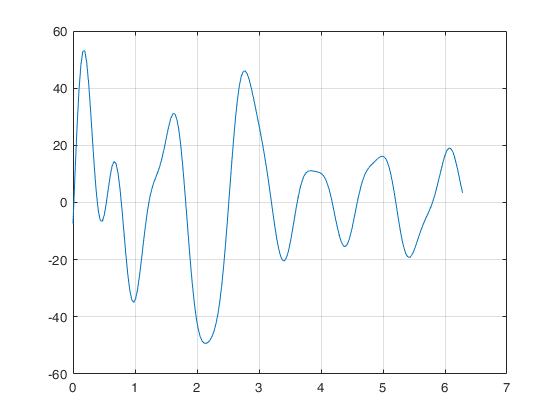

plot(0:0.1:3,double(subs(dE_sym,q_sym,0:0.1:3)));
grid on;

Stejný efekt jako u ztrátové funkce můžeme sledovat u její derivace, kde si můžeme povšimnout, že funkce má nulovou derivaci hned v několika bodech. 

Co s tím? Zavedeme moment (hybnost) → skript "BDG_moment"